# Use a pretrained network to classify images

## View image files

You can change `pathToImages` to where you'd like to download the data set

img = imread("./datasets/Training/meningioma_tumor/m (60).jpg");
imgs = imageDatastore(pathToImages + "/Training","IncludeSubfolders",true,"LabelSource","foldernames",'ReadFcn',@cropToLargestContour);

You can use the `imshow` function to display an image that is stored in a MATLAB variable:

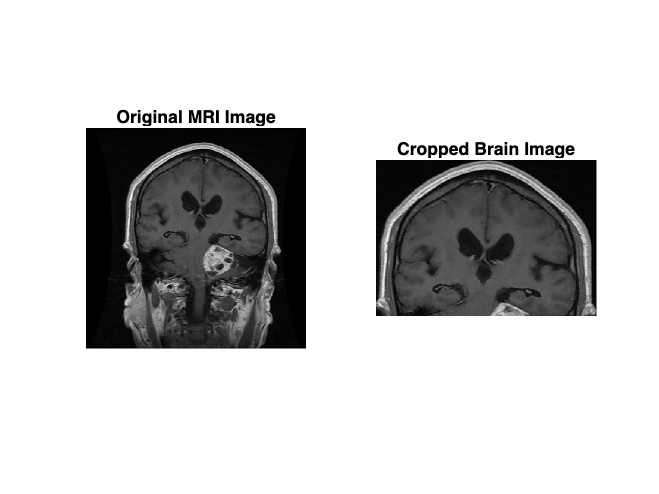

MRI = img;

% Preprocess if necessary (e.g., denoising, contrast enhancement)

% Perform edge detection using Canny edge detection
edges = edge(imadjust(rgb2gray(MRI)), 'Canny');

% Find contours of the edge-detected image
contours = bwboundaries(edges);

% Find the largest contour (assuming it corresponds to the brain boundary)
largestContour = contours{1};
maxArea = 0;
for k = 1:length(contours)
    boundary = contours{k};
    area = size(boundary, 1);
    if area > maxArea
        maxArea = area;
        largestContour = boundary;
    end
end

% Extract x and y coordinates
x = largestContour(:, 1);
y = largestContour(:, 2);

% Find top-left point
top_left = [min(x), min(y)];

% Find bottom-right point
bottom_right = [max(x), max(y)];

% Extract bounding box of the brain boundary
xmin = top_left(1);
ymin = top_left(2);
width = bottom_right(1) - xmin;
height = bottom_right(2) - ymin;

    % Extract bounding box of the brain boundary

xmin = min(largestContour(:,2));
ymin = min(largestContour(:,1));
width = max(largestContour(:,2)) - xmin;
height = max(largestContour(:,1)) - ymin;
    

% Crop the MRI image using the bounding box
croppedMRI = imcrop(MRI, [xmin ymin width height]);

% Display original and cropped images
figure;
subplot(1, 2, 1);
imshow(MRI);
title('Original MRI Image');
subplot(1, 2, 2);
imshow(croppedMRI);
title('Cropped Brain Image');


%imshow(img);

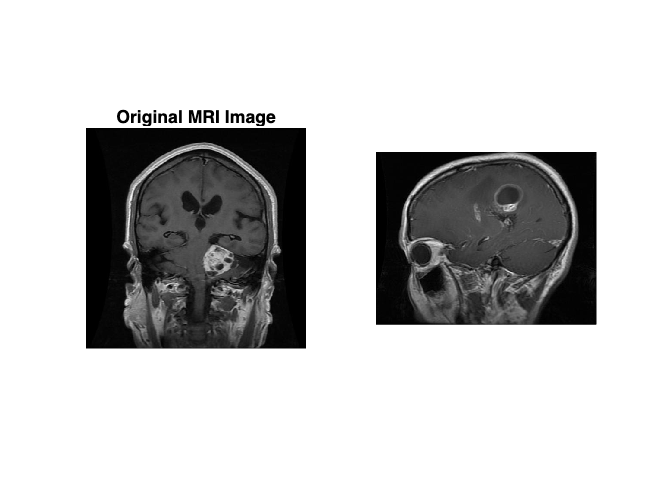

img = readimage(imgs, 121);
imshow(img)

## Classify images

You can create a copy of the predefined deep network “GoogLeNet” in the MATLAB workspace by using the `googlenet` function.

net = googlenet

You can use the `classify` function to predict the subject of an image.

%pred = classify(net,img)

GoogLeNet uses images that are 224 x 224 x 3. You need to resize the image, then classify the resized image.

pred = [];
for i=1:12
    if i < 10
        img = imread("./RandomImages/file0" + int2str(i) + ".jpg");
    else
        img = imread("./RandomImages/file" + int2str(i) + ".jpg");
    end
    imgRs = imresize(img,[224 224]);
    pred = [pred, classify(net,imgRs)];
end


pred

Determine the number of flower species

## Explore GoogLeNet

You can visualise network architecture and import a network in the Deep Network Designer.

The `net` variable we defined above represents a CNN. You can inspect the layers of the network by referencing the `Layers`property of the variable by using `variable``.``Property`indexing:

ly = net.Layers

The `ly` variable is an array of network layers. You can inspect an individual layer by indexing into `ly` with regular MATLAB array indexing:

inlayer = ly(1)

Each layer of the network has properties relevant to that type of layer. An important property of an input layer is `InputSize`, which is the size (dimensions) of images the network expects as input.

InputSize = inlayer.InputSize

Extract the last (output) layer of the network into a variable called `outlayer`.

outlayer = ly(end)

Extract the `Classes` property of the last layer of the network (stored in the variable `outlayer`).

categories = outlayer.ClassNames

## Examine predictions

The `classify` function gives the class to which the network assigns the highest score. You can obtain the predicted scores for all the classes by requesting a second output from `classify`.

[pred,scores] = classify(net,imgRs)

You can use the vector of prediction scores to investigate the network's classification. Create a bar chart of the prediction scores

bar(scores);

Create a logical array with the name `highscores`that has the value `1` (`true`) where `scores` is greater than `0.01`.

highscores = (scores > 0.01)

Use logical indexing to create a bar chart of the prediction values that are above the threshold value `0.01`.

bar(scores(highscores));

Use logical indexing and the `xticklabels` function to label the bar chart with the appropriate predicted class names. The full list of class names is stored in the `categorynames` variable.

xticklabels(categories(highscores));

Does this visualization give you some insight into the network classification of these images? Do it for other images.